Connect to ROS Master

clear
rosshutdown()

Shutting down global node /matlab_global_node_54398 with NodeURI http://192.168.86.148:58160/


prompt = "ipaddress: ";
ipaddress = input(prompt, "s");
rosinit(ipaddress, 11311)

Initializing global node /matlab_global_node_31255 with NodeURI http://192.168.86.148:58298/


Create ROS subscribers

sub.scan = rossubscriber("/scan");
sub.map = rossubscriber("/map","nav_msgs/OccupancyGrid","DataFormat","struct");
sub.coverageMap = rossubscriber("/coverage_map","nav_msgs/OccupancyGrid","DataFormat","struct");
sub.amcl = rossubscriber("/amcl_pose","geometry_msgs/PoseWithCovarianceStamped","DataFormat","struct");
sub.initialpose = rossubscriber("/initialpose","geometry_msgs/PoseWithCovarianceStamped","DataFormat","struct");


Create ROS publishers

pub.goal = rospublisher("/move_base_simple/goal","geometry_msgs/PoseStamped","DataFormat","struct");
pub.map = rospublisher("/coverage_map","nav_msgs/OccupancyGrid","DataFormat","struct");

Read and display original global map published to ROS, and intialize neural network grid

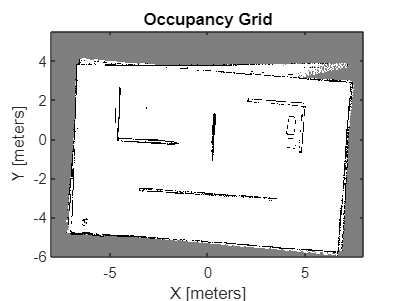

msg.map = sub.map.LatestMessage;
map = rosReadOccupancyGrid(msg.map);
show(map);

Acquire initial pose of the robot (2d pose estimate)

msg.initialpose = receive(sub.initialpose);
pos = msg.initialpose.Pose.Pose.Position;
position.initial = [pos.X, pos.Y];
position.current = position.initial;
position.current_grid_index = world2grid(map,position.current);

Republish map to coverage map topic ***(optional)***

map_msgType = rosmessage("nav_msgs/OccupancyGrid","DataFormat","struct");
map_msg = rosWriteOccupancyGrid(map_msgType,map);
send(pub.map,map_msg)
pause(0.0002)

Read coverage map from '/coverage_map' topic, acquire and transform current lidar scans to map frame 

msg.coverageMap = sub.coverageMap.LatestMessage;
map_coverage = rosReadOccupancyGrid(msg.coverageMap);
nn_mat = zeros(map_coverage.GridSize(1), map_coverage.GridSize(2));

tftree = rostf;
pause(1);
searching = 0; 
incomplete = 1; 

while incomplete == 1

msg.coverageMap = sub.coverageMap.LatestMessage;
map_coverage = rosReadOccupancyGrid(msg.coverageMap);
show(map_coverage)

transform.tf = getTransform(tftree,'map','lidar_1','Timeout',inf);
transform.quat = [transform.tf.Transform.Rotation.W,...
        transform.tf.Transform.Rotation.X,...
        transform.tf.Transform.Rotation.Y,...
        transform.tf.Transform.Rotation.Z];
transform.rotm = quat2rotm(transform.quat);
transform.trvec = [transform.tf.Transform.Translation.X,...
         transform.tf.Transform.Translation.Y ...
         transform.tf.Transform.Translation.Z];
transform.tform = trvec2tform(transform.trvec);
transform.tform(1:3,1:3) = transform.rotm(1:3,1:3);



msg.scan = sub.scan.LatestMessage;
cartScanData = msg.scan.readCartesian;
cartScanData(:,3) = 0;
homScanData = cart2hom(cartScanData);
transform.trPts = transform.tform*homScanData';
cartScanDataTransformed = hom2cart(transform.trPts');
cartScanDataTransformed(:,3) = [];

topLeft = [position.current_grid_index(1)-6, position.current_grid_index(2)-12];

- Pass in current position,

- Overlay lidar scans on map, 

- Calculate and publish next goal pose,

- Check if robot has reached goal pose using amcl localization

if searching > 15
    complete =  true;
    startlocation = grid2world(map_coverage,position.current_grid_index);

    [row,col] = find(nn_mat>0.5);
    endloc = grid2world(map_coverage,[row(1), col(1)]);

    if endloc(1) > startlocation(1)
        orientation = 0;
    elseif endloc(1) == startlocation(1)
        if endloc(2) > startlocation(2)
            orientation = pi/2;
        else
            orientation = (3*pi)/2;
        end
    else
        orientation = pi;
    end
        
    while complete

    laser_map = rosReadOccupancyGrid(msg.map);
    updateOccupancy(laser_map,cartScanDataTransformed,1);
    inflate(laser_map,0.65)

    prm = mobileRobotPRM;
    prm.Map = laser_map;
    prm.NumNodes = 100;
    prm.ConnectionDistance = 10;
    path = findpath(prm,startlocation,endloc);
    path = world2grid(map_coverage,path);

    for i = 1:1:length(path)
        prm_next_path = [path(i,1), path(i,2)]
        goal = sendPose(prm_next_path, orientation);
        send(pub.goal,goal);
        current_prm_grid_index = arrived(prm_next_path,sub.amcl);

        if current_prm_grid_index ~= prm_next_path
            startlocation = current_prm_grid_index
            break
        end
    end 
    complete = false;

    end
    searching = 0;
    position.current_grid_index = [row(1), col(1)]; 

else
    [position.next_grid_index, orientation, deadlock, nn_mat] = nextPosition(map_coverage, position.current_grid_index, nn_mat, cartScanDataTransformed);
    searching = searching + deadlock;
    goal = sendPose(map_coverage, position.next_grid_index, orientation);
    send(pub.goal,goal);
    position.current_grid_index = arrived(map_coverage, position.next_grid_index, sub.amcl);
end

Update and re-publish map

for tl_j = topLeft(2):1:topLeft(2)+24
    for tl_i = topLeft(1):1:topLeft(1)+18
        setOccupancy(map_coverage,[tl_i, tl_j],0.5,'grid')
    end 
end 

map_msg = rosWriteOccupancyGrid(map_msgType,map_coverage);
send(pub.map,map_msg)
pause(0.0002)

Stop condition to check if map/environment is completely covered 

if sum(nn_mat>=0.5, 'all') == 0
    incomplete = 0;
end 

end